# K-NN explained

Explain K-Nearest Neighbors with music

### Setup

Python environment

setup_python

Get secrets from [developer.spotify.com](https://developer.spotify.com/) 

loadenv(".env")
sp = createSpotifyClient(getenv("clientId"),getenv("clientSecret"));

### Search

query = "lucy in the sky with diamonds";
% query = "shine on your crazy diamonds";
T = searchTrack(sp,query)

T = 10x5 table
            track_id                                                            track_name                                                            artist_name                                                           album_name                                                                                 album_url                             
    ________________________    ___________________________________________________________________________________________________________    _________________________    ___________________________________________________________________________________________________________    __________________________________________________________________

    "7ioKlCkz1gjZmOBLU1mP1Z"    "Lucy in the Sky with Diamonds (Live)"                                            

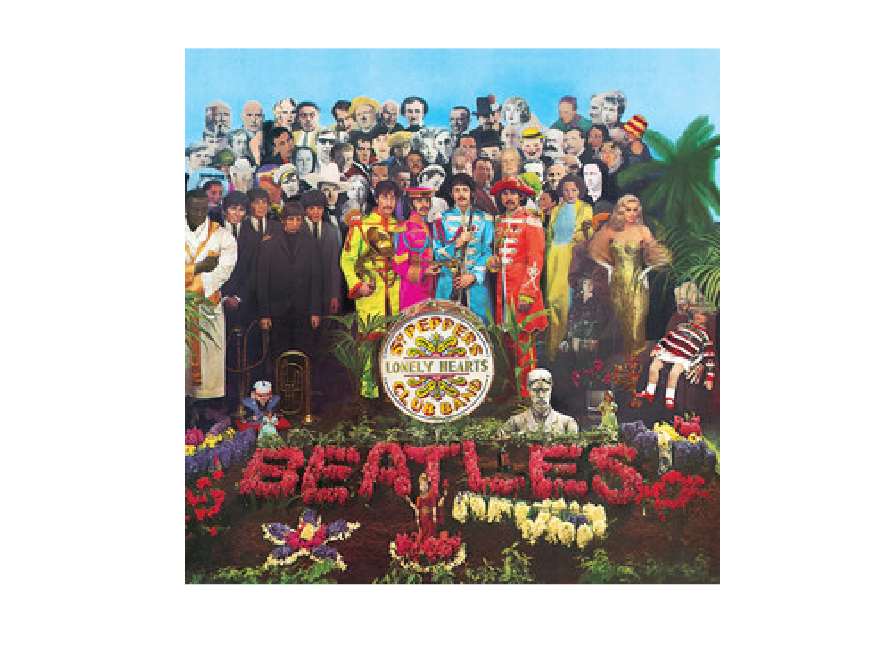

result =  T(2,:);
imshow(imread(result.album_url))

track_features = getFeatures(sp,result.track_id)

track_features = struct with fields:
        acousticness: 0.0469
        danceability: 0.3110
              energy: 0.3250
    instrumentalness: 0
            liveness: 0.1390
         speechiness: 0.0283
             valence: 0.6680


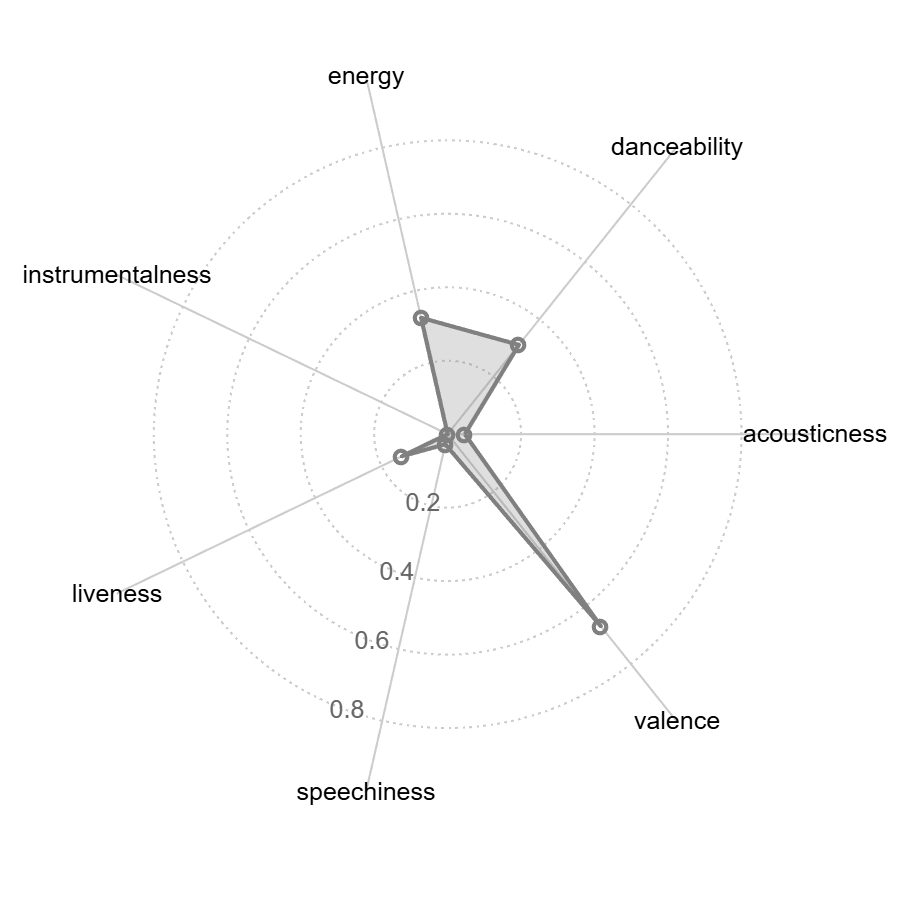

plotFeatures(track_features)

### Utils

function sp = createSpotifyClient(clientId,clientSecret)
    spotipy = py.importlib.import_module('spotipy');
    auth_manager = spotipy.oauth2.SpotifyClientCredentials(client_id=clientId, client_secret=clientSecret);
    sp = spotipy.Spotify(auth_manager = auth_manager);
end

function result = searchTrack1(sp,query)
    res = sp.search(q="track: "+ query, type = "track");
    items = res{'tracks'}{'items'};
    result.track_id = string(items{1}{'id'});
    result.track_name = string(items{1}{'name'});
    result.track_artist = string(items{1}{'artists'}{1}{'name'});
    result.track_album = string(items{1}{'album'}{'name'});
end

function T = searchTrack(sp, query)
res = sp.search(q="track: "+ query, type = "track");
items = res{'tracks'}{'items'};
result = pyrun("track_results = [{" + ...
    "'track_id': item['id']," + ...
    "'track_name': item['name']," + ...
    "'artist_name': item['artists'][0]['name']," + ...
    "'album_name': item['album']['name']," + ...
    "'album_url': item['album']['images'][1]['url']}" + ...
    "for item in items]", "track_results",items=items);
T = table(py.pandas.DataFrame(result));
end

function track_features = getFeatures(sp,track_id)
    track_features = sp.audio_features(track_id);
    track_features = struct(track_features{1});
    labels = {'acousticness','danceability','energy','instrumentalness','liveness','speechiness','valence'};
    allFields = fieldnames(track_features);
    toRemove  = setdiff(allFields, labels);
    track_features = rmfield(track_features, toRemove);
    track_features = orderfields(track_features);
    % loop over each field and cast to double
    for k = 1:numel(labels)
        track_features.(labels{k}) = double(track_features.(labels{k}));
    end
end

function plotFeatures(track_features)
    % --- Given struct of track features ------------------------------------
    % track_features = struct( ...
    %    'danceability',    0.5170, ...
    %    'energy',          0.5060, ...
    %    'loudness',       -10.9180, ...
    %    'speechiness',     0.0311, ...
    %    'acousticness',    0.4310, ...
    %    'instrumentalness',9.6000e-04, ...
    %    'liveness',        0.9660, ...
    %    'valence',         0.4570);
    
    % 1) Extract labels & values
    labels = fieldnames(track_features);
    stats  = cell2mat(struct2cell(track_features))';   % row vector
    
    % 2) Close the loop
    nVars = numel(stats);
    theta = linspace(0,2*pi,nVars+1);   % includes endpoint 2π
    rho   = [stats, stats(1)];          % append first stat at end
    
    % 3) Convert to Cartesian
    [x, y] = pol2cart(theta, rho);
    
    % --- Build the plot -----------------------------------------------------
    figure('Position',[100 100 600 600]);
    hold on;
    axis equal off;
    
    % 4) Draw radial grid circles
    rTicks = [0.2 0.4 0.6 0.8];
    tGrid  = linspace(0,2*pi,200);
    for r = rTicks
        plot(r*cos(tGrid), r*sin(tGrid), ':', 'LineWidth', 1, 'Color', [0.8 0.8 0.8]);
    end
    
    % 5) Draw spokes
    for k = 1:nVars
        th = theta(k);
        plot([0 cos(th)], [0 sin(th)], '-', 'LineWidth', 1, 'Color', [0.8 0.8 0.8]);
    end
    
    % 6) Fill area & outline
    fill(x, y, 0.5*[1 1 1], 'FaceAlpha', 0.25, 'EdgeColor', 'none');
    plot(x, y, '-o', 'LineWidth', 2, 'Color', 0.5*[1 1 1]);
    
    % 7) Feature labels around the outside
    labelRadius = 1;  % just outside the unit circle
    for k = 1:nVars
        th = theta(k);
        text(labelRadius*cos(th), labelRadius*sin(th), labels{k}, ...
             'FontSize', 12, 'HorizontalAlignment', 'center');
    end
    
    % 8) Radial-tick labels at ~250°
    labelAngle = deg2rad(250);
    for r = rTicks
        text(r*cos(labelAngle), r*sin(labelAngle), sprintf('%.1f', r), ...
             'FontSize', 12, 'Color', [0.4 0.4 0.4], ...
             'HorizontalAlignment','center');
    end
    
    % title('Track Feature Radar Chart');
    hold off;
end

export livescript.mlx README.md;